# Irminger 3 CTD Casts

First produces a rough map of the CTD casts from Irminger 3 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen.

Kristen Fogaren 12/3/2020 

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

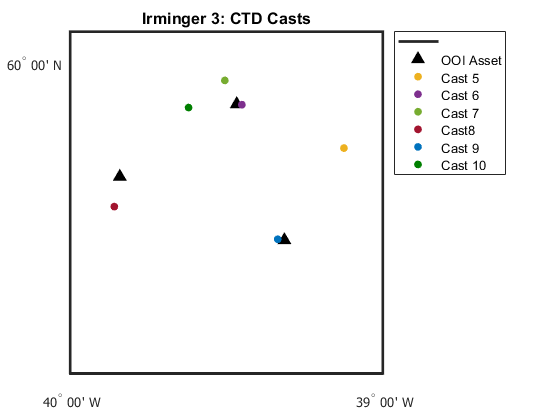

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year3')
load Irm3_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(ar0701005down.latitude),nanmean(ar0701005down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(ar0701006down.latitude),nanmean(ar0701006down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(ar0701007down.latitude),nanmean(ar0701007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(ar0701008down.latitude),nanmean(ar0701008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(ar0701009down.latitude),nanmean(ar0701009down.longitude),'.','markersize',20,'Color',blue)
plotm(nanmean(ar0701010down.latitude),nanmean(ar0701010down.longitude),'.','markersize',20,'Color',forestgreen)


title('Irminger 3: CTD Casts')
legend('','OOI Asset','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Location','bestoutside')

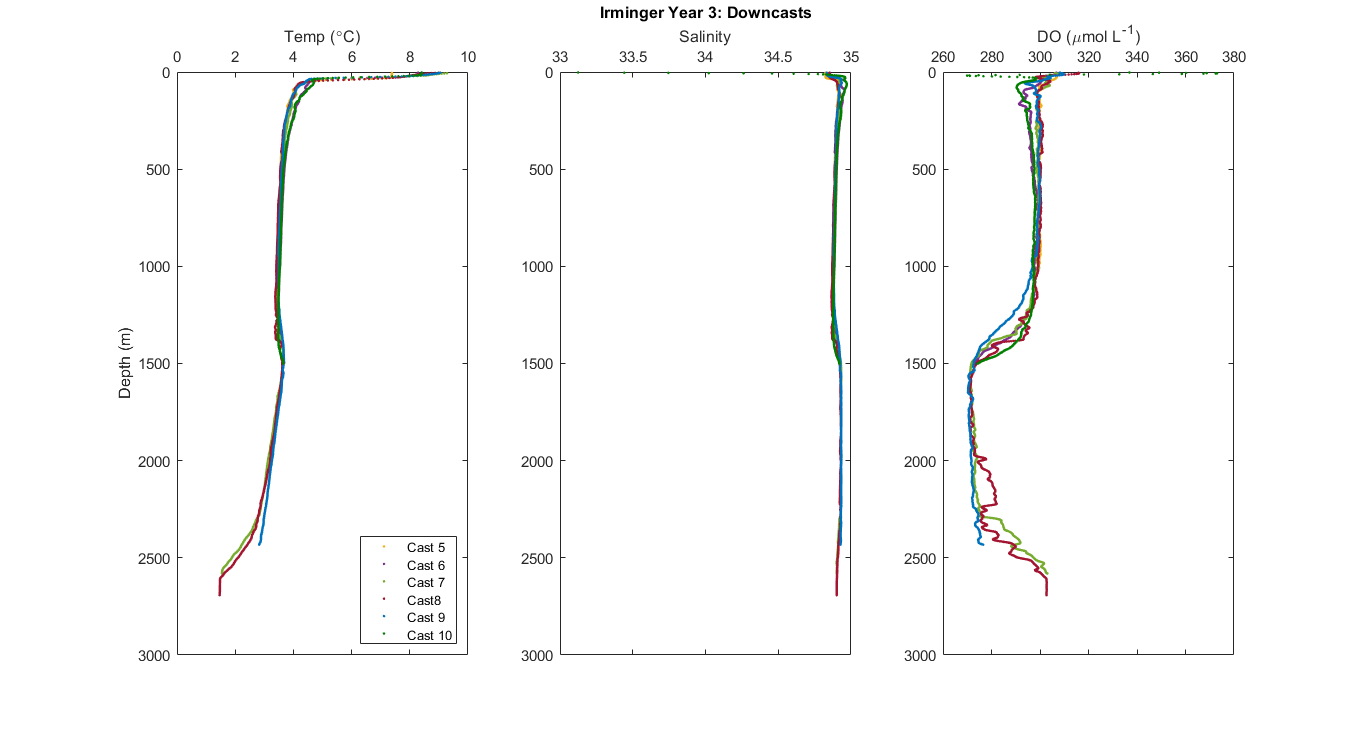

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701005down.t090C,ar0701005down.depSM,'.','Color',yellow)
hold on
plot(ar0701006down.t090C,ar0701006down.depSM,'.','Color',purple)
plot(ar0701007down.t090C,ar0701007down.depSM,'.','Color',green)
plot(ar0701008down.t090C,ar0701008down.depSM,'.','Color',maroon)
plot(ar0701009down.t090C,ar0701009down.depSM,'.','Color',blue)
plot(ar0701010down.t090C,ar0701010down.depSM,'.','Color',forestgreen)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701005down.sal00,ar0701005down.depSM,'.','Color',yellow)
hold on
plot(ar0701006down.sal00,ar0701006down.depSM,'.','Color',purple)
plot(ar0701007down.sal00,ar0701007down.depSM,'.','Color',green)
plot(ar0701008down.sal00,ar0701008down.depSM,'.','Color',maroon)
plot(ar0701009down.sal00,ar0701009down.depSM,'.','Color',blue)
plot(ar0701010down.sal00,ar0701010down.depSM,'.','Color',forestgreen)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Downcasts')

s3 = subplot(1,3,3);
plot(ar0701005down.sbeox0MLL*44.661,ar0701005down.depSM,'.','Color',yellow)
hold on
plot(ar0701006down.sbeox0MLL*44.661,ar0701006down.depSM,'.','Color',purple)
plot(ar0701007down.sbeox0MLL*44.661,ar0701007down.depSM,'.','Color',green)
plot(ar0701008down.sbeox0MLL*44.661,ar0701008down.depSM,'.','Color',maroon)
plot(ar0701009down.sbeox0MLL*44.661,ar0701009down.depSM,'.','Color',blue)
plot(ar0701010down.sbeox0MLL*44.661,ar0701010down.depSM,'.','Color',forestgreen)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

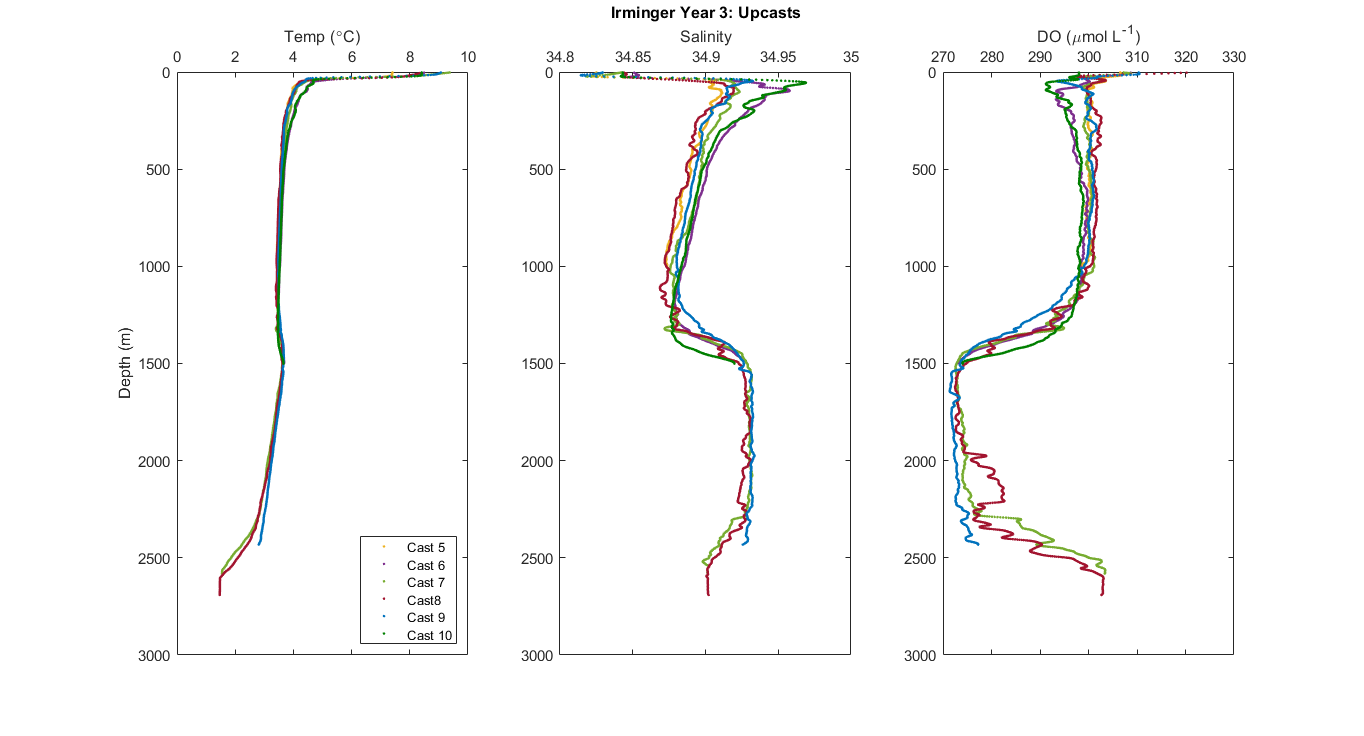

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701005up.t090C,ar0701005up.depSM,'.','Color',yellow)
hold on
plot(ar0701006up.t090C,ar0701006up.depSM,'.','Color',purple)
plot(ar0701007up.t090C,ar0701007up.depSM,'.','Color',green)
plot(ar0701008up.t090C,ar0701008up.depSM,'.','Color',maroon)
plot(ar0701009up.t090C,ar0701009up.depSM,'.','Color',blue)
plot(ar0701010up.t090C,ar0701010up.depSM,'.','Color',forestgreen)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701005up.sal00,ar0701005up.depSM,'.','Color',yellow)
hold on
plot(ar0701006up.sal00,ar0701006up.depSM,'.','Color',purple)
plot(ar0701007up.sal00,ar0701007up.depSM,'.','Color',green)
plot(ar0701008up.sal00,ar0701008up.depSM,'.','Color',maroon)
plot(ar0701009up.sal00,ar0701009up.depSM,'.','Color',blue)
plot(ar0701010up.sal00,ar0701010up.depSM,'.','Color',forestgreen)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Upcasts')

s3 = subplot(1,3,3);
plot(ar0701005up.sbeox0MLL*44.661,ar0701005up.depSM,'.','Color',yellow)
hold on
plot(ar0701006up.sbeox0MLL*44.661,ar0701006up.depSM,'.','Color',purple)
plot(ar0701007up.sbeox0MLL*44.661,ar0701007up.depSM,'.','Color',green)
plot(ar0701008up.sbeox0MLL*44.661,ar0701008up.depSM,'.','Color',maroon)
plot(ar0701009up.sbeox0MLL*44.661,ar0701009up.depSM,'.','Color',blue)
plot(ar0701010up.sbeox0MLL*44.661,ar0701010up.depSM,'.','Color',forestgreen)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

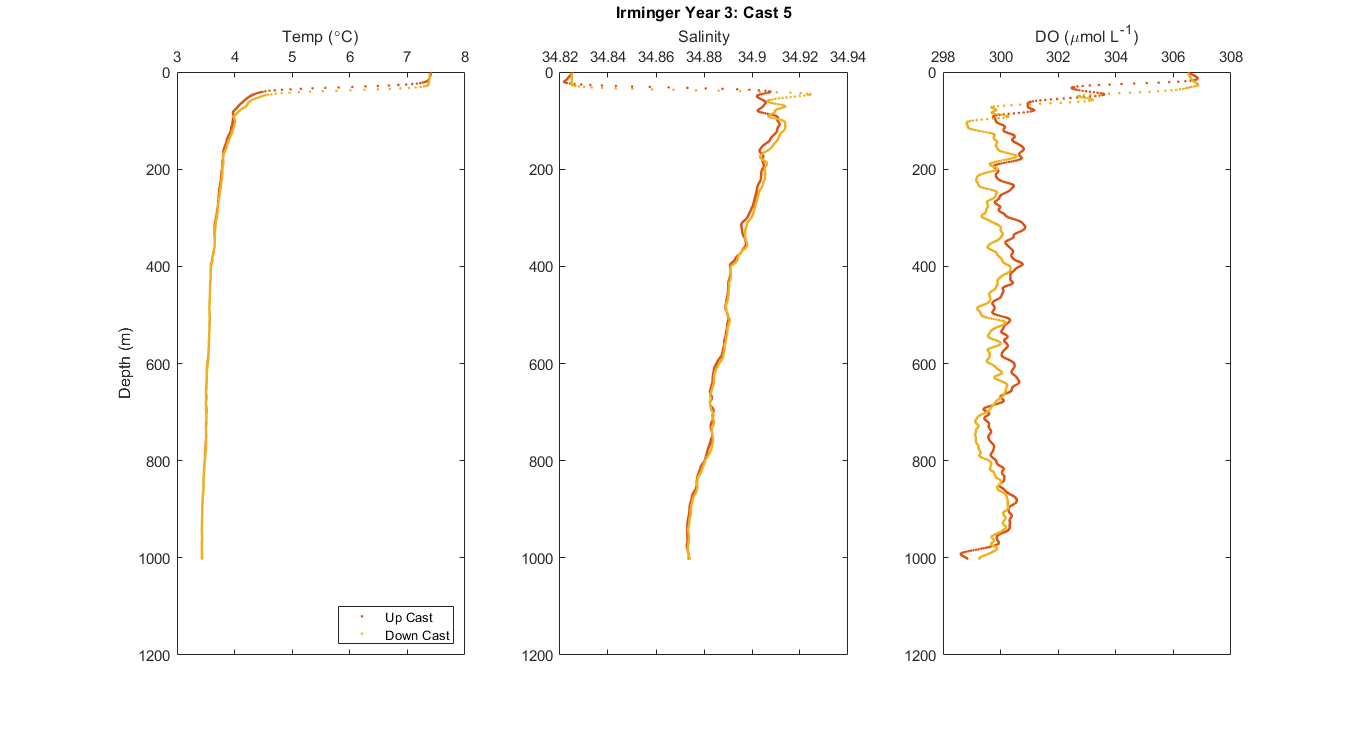

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701005up.t090C,ar0701005up.depSM,'.','Color',red);
hold on
plot(ar0701005down.t090C,ar0701005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701005up.sal00,ar0701005up.depSM,'.','Color',red);
hold on
plot(ar0701005down.sal00,ar0701005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 5')

s3 = subplot(1,3,3);
plot(ar0701005up.sbeox0MLL*44.661,ar0701005up.depSM,'.','Color',red);
hold on
plot(ar0701005down.sbeox0MLL*44.661,ar0701005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

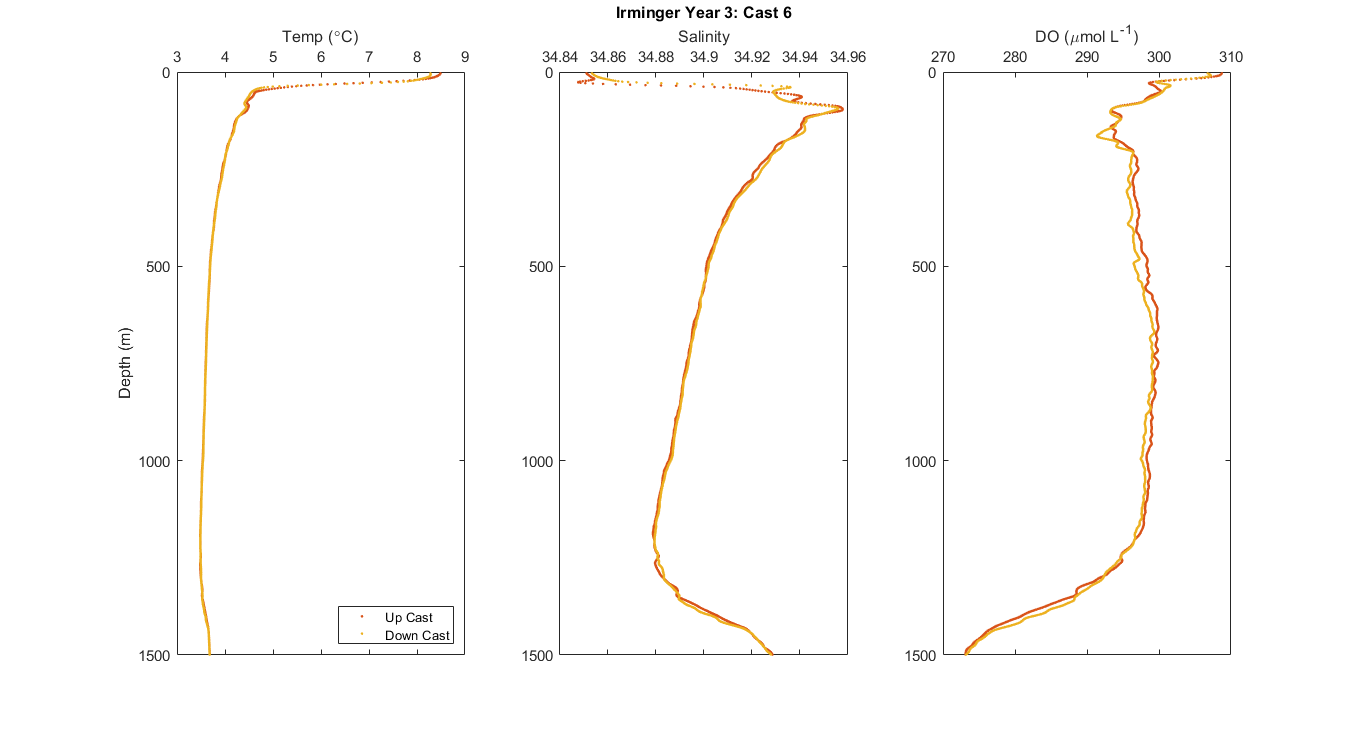

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701006up.t090C,ar0701006up.depSM,'.','Color',red);
hold on
plot(ar0701006down.t090C,ar0701006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701006up.sal00,ar0701006up.depSM,'.','Color',red);
hold on
plot(ar0701006down.sal00,ar0701006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 6')

s3 = subplot(1,3,3);
plot(ar0701006up.sbeox0MLL*44.661,ar0701006up.depSM,'.','Color',red);
hold on
plot(ar0701006down.sbeox0MLL*44.661,ar0701006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

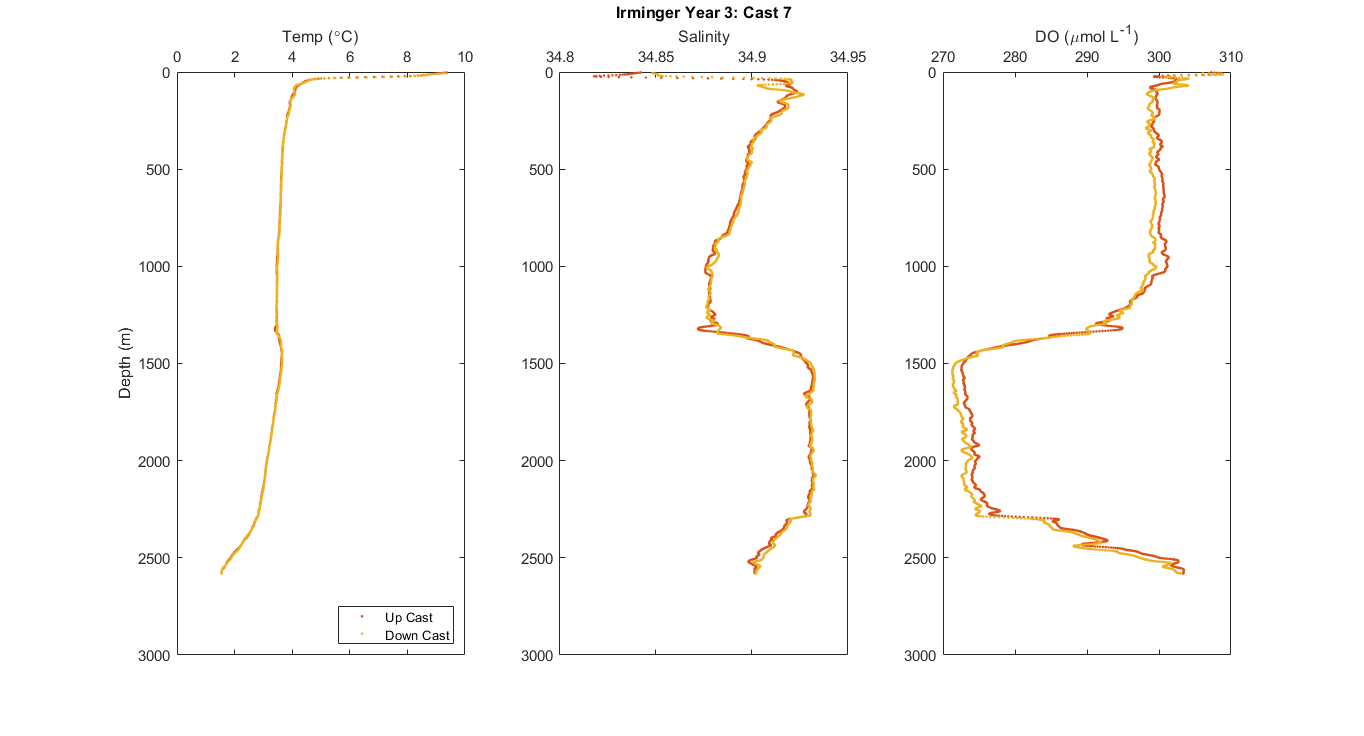

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701007up.t090C,ar0701007up.depSM,'.','Color',red);
hold on
plot(ar0701007down.t090C,ar0701007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701007up.sal00,ar0701007up.depSM,'.','Color',red);
hold on
plot(ar0701007down.sal00,ar0701007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 7')

s3 = subplot(1,3,3);
plot(ar0701007up.sbeox0MLL*44.661,ar0701007up.depSM,'.','Color',red);
hold on
plot(ar0701007down.sbeox0MLL*44.661,ar0701007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

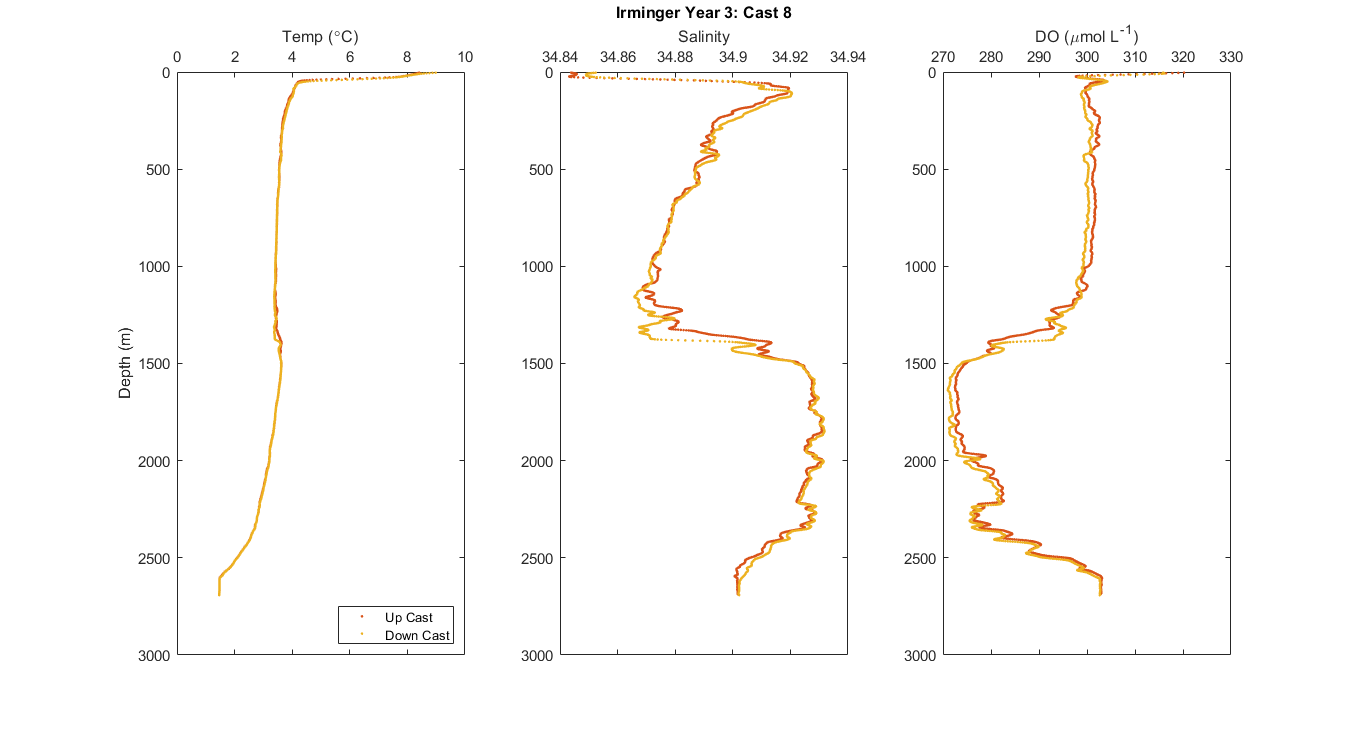

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701008up.t090C,ar0701008up.depSM,'.','Color',red);
hold on
plot(ar0701008down.t090C,ar0701008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701008up.sal00,ar0701008up.depSM,'.','Color',red);
hold on
plot(ar0701008down.sal00,ar0701008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 8')

s3 = subplot(1,3,3);
plot(ar0701008up.sbeox0MLL*44.661,ar0701008up.depSM,'.','Color',red);
hold on
plot(ar0701008down.sbeox0MLL*44.661,ar0701008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

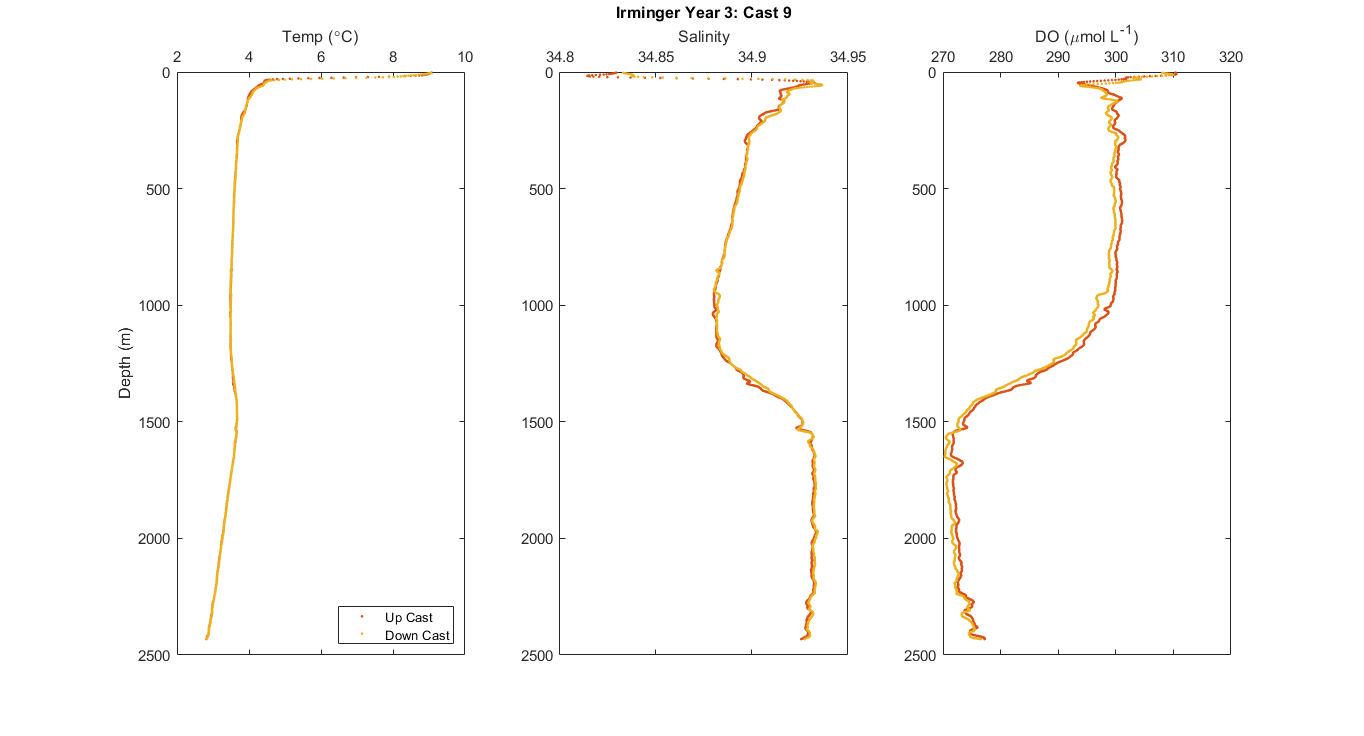


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701009up.t090C,ar0701009up.depSM,'.','Color',red);
hold on
plot(ar0701009down.t090C,ar0701009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701009up.sal00,ar0701009up.depSM,'.','Color',red);
hold on
plot(ar0701009down.sal00,ar0701009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 9')

s3 = subplot(1,3,3);
plot(ar0701009up.sbeox0MLL*44.661,ar0701009up.depSM,'.','Color',red);
hold on
plot(ar0701009down.sbeox0MLL*44.661,ar0701009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

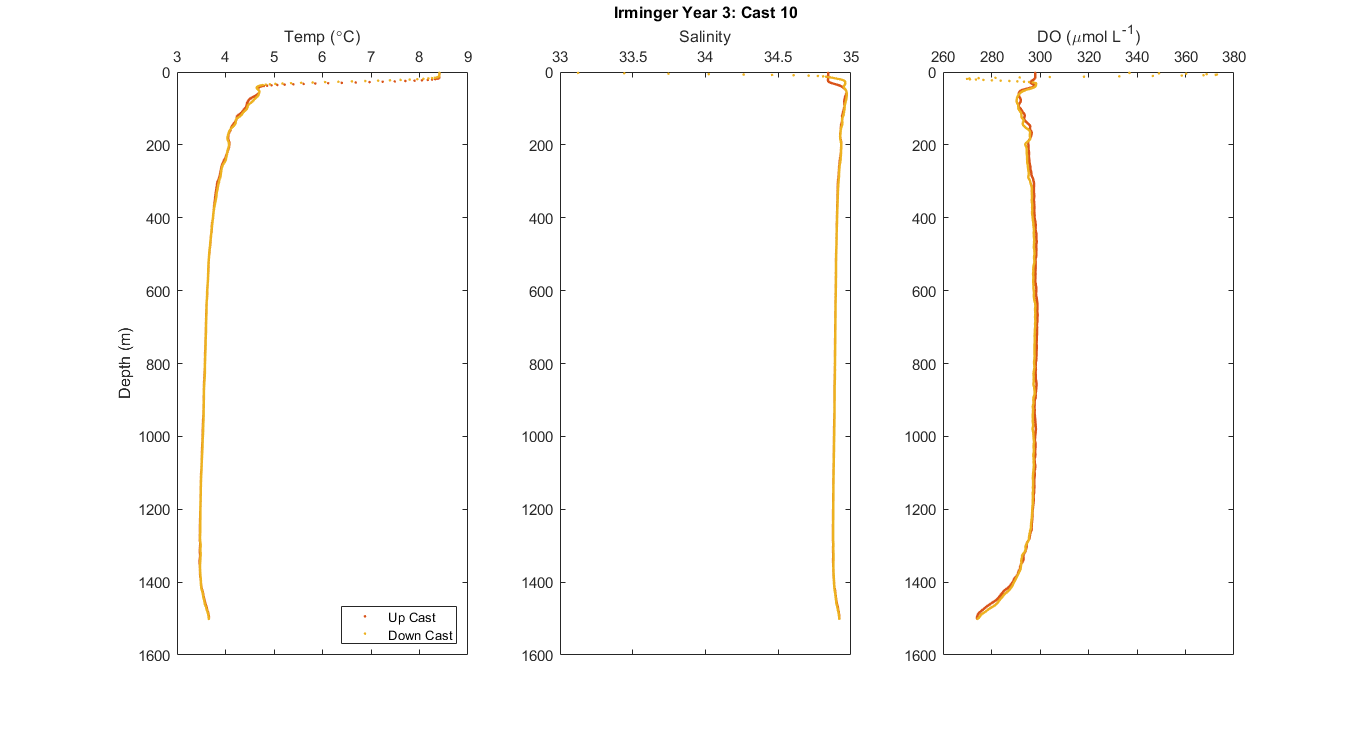


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(ar0701010up.t090C,ar0701010up.depSM,'.','Color',red);
hold on
plot(ar0701010down.t090C,ar0701010down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(ar0701010up.sal00,ar0701010up.depSM,'.','Color',red);
hold on
plot(ar0701010down.sal00,ar0701010down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 3: Cast 10')

s3 = subplot(1,3,3);
plot(ar0701010up.sbeox0MLL*44.661,ar0701010up.depSM,'.','Color',red);
hold on
plot(ar0701010down.sbeox0MLL*44.661,ar0701010down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')